# Pitch Plane Half Car Model Analysis

Before this, be sure to clone:

[https://github.com/Alphabet1671/FSAE-VD-Personal-Scripts](https://github.com/Alphabet1671/FSAE-VD-Personal-Scripts)

and add /Vertical Dynamics/ to the directory.


car.sprungMass = 962; % kg
car.pitchInertia = 1968; % whatever tf the SI unit is for this
car.unsprungMass = 35; % kg
car.wheelbase = 1.53; % m
car.CGx = (300+302)/962; % ratio fwd
car.CGh = 1.43*0.37; % m

car.frontInertance = 0; % kg
car.rearInertance = 0; % kg
car.frontTireStiffness = 150000; % N/m
car.frontTireDamping = 400; % Ns/m
car.rearTireStiffness = 150000;
car.rearTireDamping = 400;


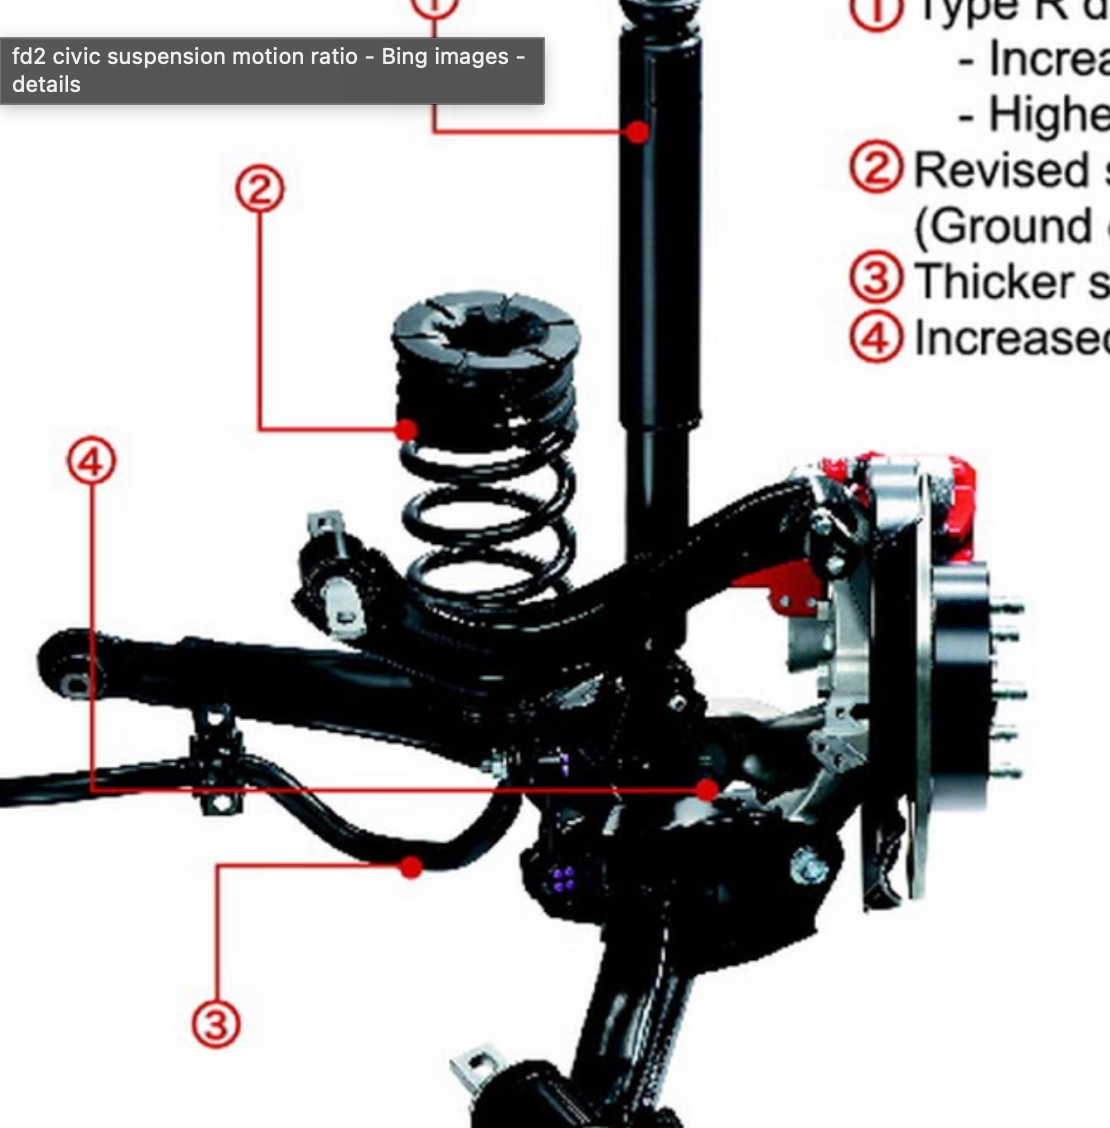

Eyeballing this, MR = 0.5 for rear, MR = 1 for front bc strut


frontSpringRate = 100e3;
rearSpringRate = 80e3;

frontWheelRate = frontSpringRate;
rearWheelRate = rearSpringRate*0.5^2;

frontSpring = [0,1;0,frontSpringRate];
rearSpring = [0,1;0,rearSpringRate];

frontDampingSweep = 0:1000:10000;
rearDampingSweep = 0:1000:15000;

frontMinCPL = zeros(length(frontDampingSweep), length(rearDampingSweep));
rearMinCPL = zeros(length(frontDampingSweep), length(rearDampingSweep));
zeta = zeros(length(frontDampingSweep), length(rearDampingSweep));
hubPitch = zeros(length(frontDampingSweep), length(rearDampingSweep));
bodyPitch = zeros(length(frontDampingSweep), length(rearDampingSweep));

for i = 1:length(frontDampingSweep)
    frontDamper = [0,1;0,frontDampingSweep(i)];
    parfor j = 1:length(rearDampingSweep)
        rearDamper = [0,1;0,rearDampingSweep(j)];
        run = SingleRun(car, frontDamper, rearDamper, frontSpring, rearSpring);
        KPI = CalculateKPI(run);
        frontMinCPL(i,j) = KPI.frontMinCPL;
        rearMinCPL(i,j) = KPI.rearMinCPL;
        zeta(i,j) = KPI.heaveZeta;
        hubPitch(i,j) = KPI.hubPitchRMS;
        bodyPitch(i,j) = KPI.bodyPitchRMS;
    end
end



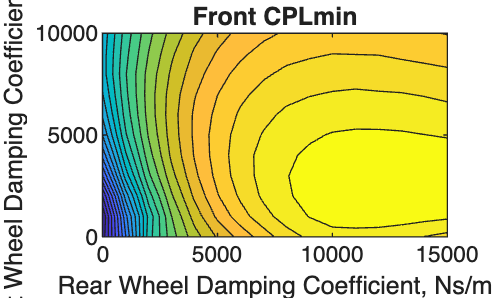

% plotting
figure
contourf(rearDampingSweep, frontDampingSweep, frontMinCPL, 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("Front CPLmin");

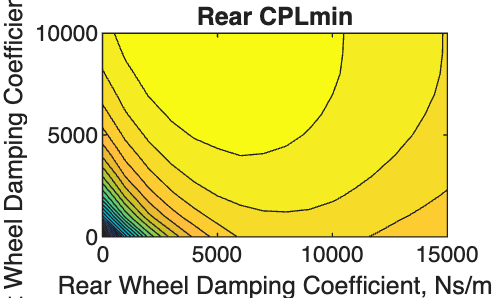


figure
contourf(rearDampingSweep, frontDampingSweep, rearMinCPL, 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("Rear CPLmin")

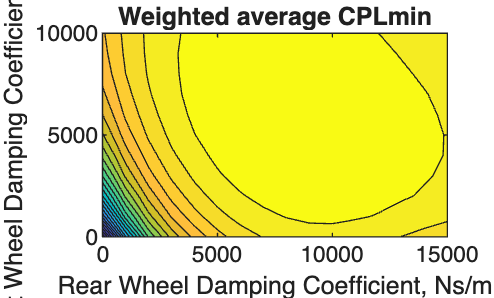


figure
contourf(rearDampingSweep, frontDampingSweep, frontMinCPL*car.CGx+rearMinCPL*(1-car.CGx), 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("Weighted average CPLmin")

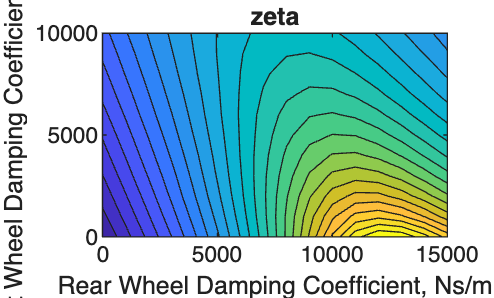


figure
contourf(rearDampingSweep, frontDampingSweep, zeta, 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("zeta")

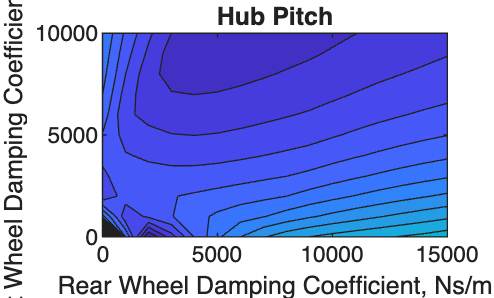


figure
contourf(rearDampingSweep, frontDampingSweep, hubPitch, 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("Hub Pitch")

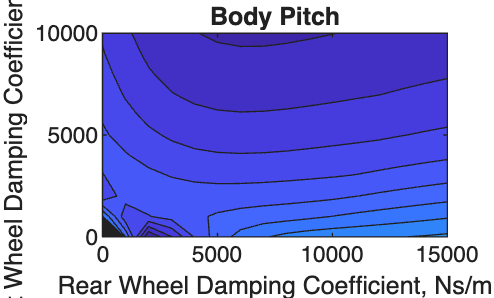


figure
contourf(rearDampingSweep, frontDampingSweep, bodyPitch, 25);
xlabel("Rear Wheel Damping Coefficient, Ns/m");
ylabel("Front Wheel Damping Coefficient, Ns/m");
title("Body Pitch")